# **Categorical Colors - Examples**

### EXAMPLE 1 - Print a list of all available color palettes

load categorical_palettes.mat
disp(categorical_palettes)

        actonS: [100x3 double]
       bamakoS: [100x3 double]
       batlowS: [100x3 double]
      batlowKS: [100x3 double]
      batlowWS: [100x3 double]
       bilbaoS: [100x3 double]
         budaS: [100x3 double]
        davosS: [100x3 double]
        devonS: [100x3 double]
      glasgowS: [100x3 double]
        grayCS: [100x3 double]
       hawaiiS: [100x3 double]
        imolaS: [100x3 double]
      lajollaS: [100x3 double]
        lapazS: [100x3 double]
       lipariS: [100x3 double]
        naviaS: [100x3 double]
       naviaWS: [100x3 double]
         nuukS: [100x3 double]
         osloS: [100x3 double]
        tokyoS: [100x3 double]
        turkuS: [100x3 double]
        accent: [8x3 double]
         dark2: [8x3 double]
        paired: [12x3 double]
       pastel1: [9x3 double]
       pastel2: [8x3 double]
          set1: [9x3 double]
          set2: [8x3 double]
          set3: [12x3 double]
          bold: [10x3 double]
    colorblind: [8x3 double]
        prism2: [10x3 dou

### EXAMPLE 2 - Get the first five colors from the `'imola'` color palette

**Tip**: It is not necessary to include the 'S' at the end of a palette name.

imola = cat_colors('imola',5);
disp(imola)

    0.1014    0.2001    0.7002
    1.0000    1.0000    0.4001
    0.3289    0.5263    0.4976
    0.1885    0.3682    0.6150
    0.5672    0.7663    0.4343



### EXAMPLE 3 - Apply categorical colors to a figure

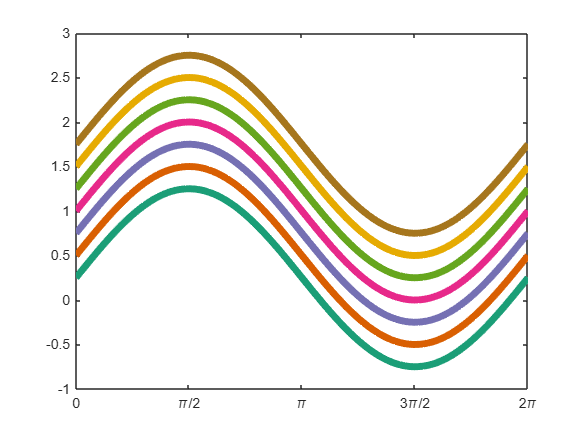

% Define data
x = linspace(0,2*pi,100);
y1 = sin(x)+0.25;
y2 = sin(x)+0.50;
y3 = sin(x)+0.75;
y4 = sin(x)+1.00;
y5 = sin(x)+1.25;
y6 = sin(x)+1.50;
y7 = sin(x)+1.75;
Y = [y1' y2' y3' y4' y5' y6' y7'];
% Create figure
figure(1)
plot(x,Y,'LineWidth',5)
 set(gca,'XTick',0:pi/2:2*pi) 
 set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
 axis padded, xlim([0 2*pi])
% Change colororder to categorical colors
C = cat_colors('dark'); % From Colorbrewer2
colororder(gca,C)

### EXAMPLE 4 - Add a categorical colorbar to a figure

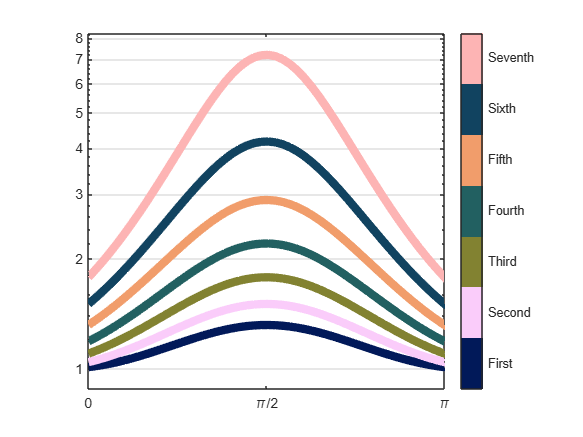

% Create figure
figure(2)
plot(x,Y./sin(Y),'LineWidth',6)
 set(gca,'XTick',0:pi/2:2*pi,'YScale','log','YMinorGrid','off','YGrid','on') 
 set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
 axis padded square, xlim([0 pi])
% Change colororder to categorical colors
C = cat_colors('batlow'); % From Crameri et al. (2020)
colororder(gca,C)
% Define the color labels
labels = {'First','Second','Third','Fourth','Fifth','Sixth','Seventh'};
% Add a categorical colorbar
cat_colorbar(C,labels,false); % 3rd input flips the colorbar

### EXAMPLE 5 - View all categorical color palettes as bar charts

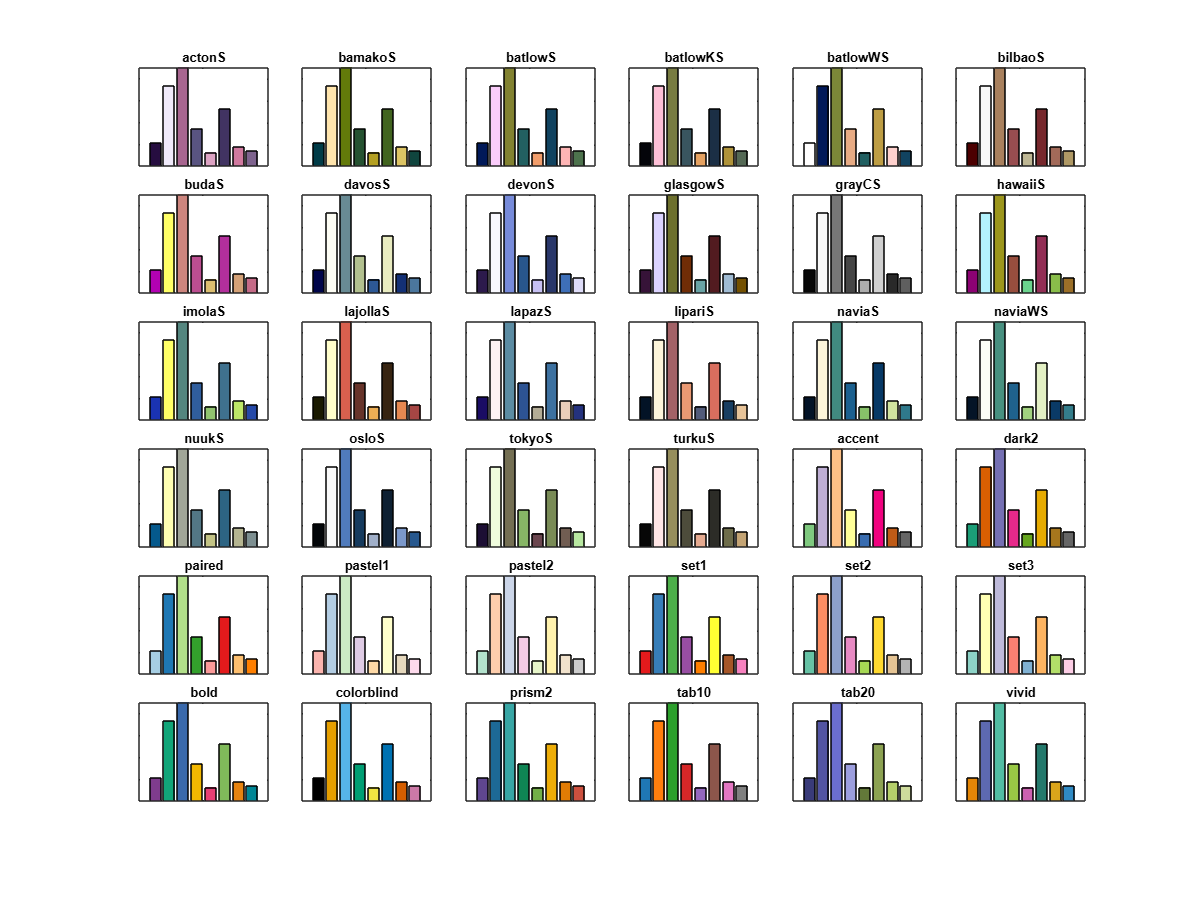

rng(0)
yData = abs(randn([1 8]).*2);

palette_names = fieldnames(categorical_palettes);
number_of_palettes = length(palette_names);

sc=3;
figure('units','inches','position',[0 0 4*sc 3*sc])
tiledlayout(6,6);
for i = 1:number_of_palettes
 nexttile
 barplot(yData,palette_names{i}) % Local function
 title(palette_names{i})
end

function barplot(Y,color_palette)
     bar(1,Y,'grouped');
     set(gca,'XTickLabels',[],'YTickLabels',[])
     C = cat_colors(color_palette,8);
     colororder(gca,C)
end

#### References

Brewer, C. M. (2004). Colorbrewer2. [https://colorbrewer2.org/](https://colorbrewer2.org/)

Crameri, F., Shephard, G. E., & Heron, P. J. (2020). The misuse of colour in science communication. *Nature Communications*, **11**(1), 5444. [https://doi.org/10.1038/s41467-020-19160-7](https://doi.org/10.1038/s41467-020-19160-7)

Wong, B. Points of view: Color blindness. *Nat Methods* **8**, 441 (2011). [https://doi.org/10.1038/nmeth.1618](https://doi.org/10.1038/nmeth.1618) 